close all;
clear;
clc;

%Navigate to folder that contains the csv/txt files
cd ../Desktop/

%Input files must be csv files

%LTS_V2 input file names
datafile = "resistorsTest.csv";
datafile1 = "capacitorsTest.csv";
datafile2 = "inductorsTest.csv";
datafile3 = "VSTest.csv";
datafile4 = "CSTest.csv";
datafile5 = "VCVSTest.csv";
datafile6 = "VCCSTest.csv";
datafile7 = "CCVSTest.csv";
datafile8 = "CCCSTest.csv";
datafile9 = "OpAmpTest.csv";
datafile10 = "AcDiodeTest.csv";
datafile11 = "DcDiodeTest.csv";

graphTitle = "Scalability Test - Linear Components";
yAxisName = "Time taken to finish simulation (s)";
xAxisName = "Series component count";


%Get the data
simfile = importdata(datafile, ",", 1);
simdata = simfile.data;
simfile1 = importdata(datafile1, ",", 1);
simdata1 = simfile1.data;
simfile2 = importdata(datafile2, ",", 1);
simdata2 = simfile2.data;
simfile3 = importdata(datafile3, ",", 1);
simdata3 = simfile3.data;
simfile4 = importdata(datafile4, ",", 1);
simdata4 = simfile4.data;
simfile5 = importdata(datafile5, ",", 1);
simdata5 = simfile5.data;
simfile6 = importdata(datafile6, ",", 1);
simdata6 = simfile6.data;
simfile7 = importdata(datafile7, ",", 1);
simdata7 = simfile7.data;
simfile8 = importdata(datafile8, ",", 1);
simdata8 = simfile8.data;
simfile9 = importdata(datafile9, ",", 1);
simdata9 = simfile9.data;
simfile10 = importdata(datafile10, ",", 1);
simdata10 = simfile10.data;
simfile11 = importdata(datafile11, ",", 1);
simdata11 = simfile11.data;


%plot the data
figure;

%linear
plot(simdata(:,1),simdata(:,2),'LineWidth',2,'Color', [.2, .3, .5]);
hold on;
plot(simdata1(:,1),simdata1(:,2),'LineWidth',2,'Color', [.2, .8, .7]);
plot(simdata2(:,1),simdata2(:,2),'LineWidth',2,'Color', [1, .1, 1]);
plot(simdata3(:,1),simdata3(:,2),'LineWidth',2,'Color', [.1, .2, .3]);
plot(simdata4(:,1),simdata4(:,2),'LineWidth',2,'Color', [.2, .2, .9]);
plot(simdata5(:,1),simdata5(:,2),'LineWidth',2);
plot(simdata6(:,1),simdata6(:,2),'LineWidth',2);
plot(simdata7(:,1),simdata7(:,2),'LineWidth',2);
plot(simdata8(:,1),simdata8(:,2),'LineWidth',2);
plot(simdata9(:,1),simdata9(:,2),'LineWidth',2);

%non-linear
% plot(simdata10(:,1),simdata10(:,2),'LineWidth',2);
% plot(simdata11(:,1),simdata11(:,2),'LineWidth',2);

title(graphTitle);
ylabel(yAxisName);
xlabel(xAxisName);
legend(["Resistor","Capacitor","Inductor","Voltage Source","Current Source","Voltage Controlled Voltage Source","Voltage Controlled Current Source","Current Controlled Voltage Source","Current Controlled Current Source","Ideal Op-Amp","AC Diode","DC Diode"], "NumColumns", 2);

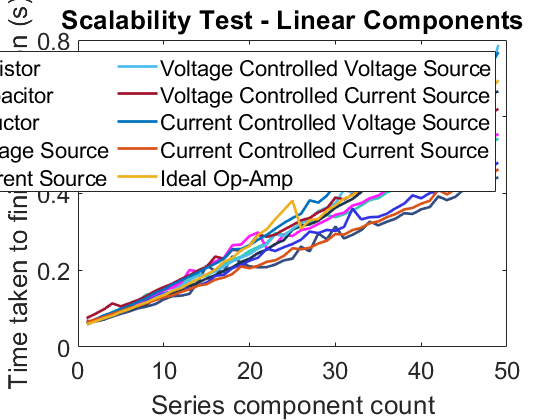

% legend("AC Diode","DC Diode");
% set(gca,'Fontsize',18, 'YScale','log');
set(gca,'Fontsize',18);
hold off;